# Lab 3: Convolution and Filtering

addpath('resources','scripts');

## Question 3.1

load('dataset3.mat');
x = xs;
b0 = [1/3, 1/3, 1/3];
a = 1;
y = filter(b0, a, x);

y0 = h0x0 + h1x-1 + h2x-2

y1 = h0x1 + h1x0 + h2x-1

y2 = h0x2 + h1x1 + h2x0, ... (until ... xn+length(h))

## Question 3.2

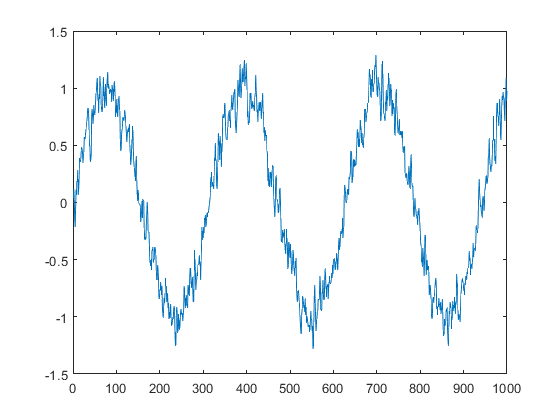

plot0 = plot(y);

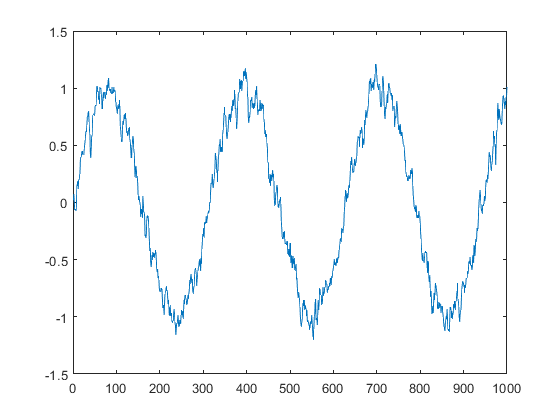


b1 = 1/5+zeros(1,5);
b2 = 1/10+zeros(1,10);
b3 = 1/20+zeros(1,20);
b4 = 1/30+zeros(1,30);
b5 = 1/50+zeros(1,50);

y1 = filter(b1, a, x);
y2 = filter(b2, a, x);
y3 = filter(b3, a, x);
y4 = filter(b4, a, x);
y5 = filter(b5, a, x);

plot1 = plot(y1);

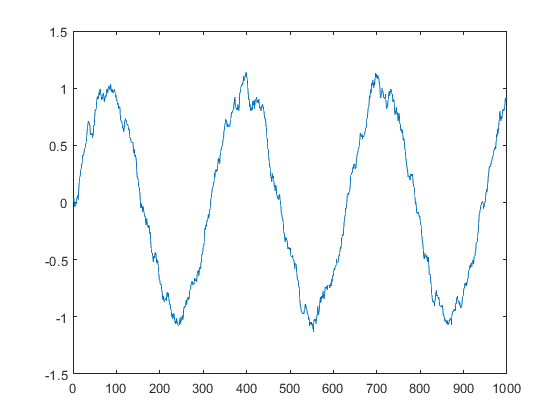

plot2 = plot(y2);

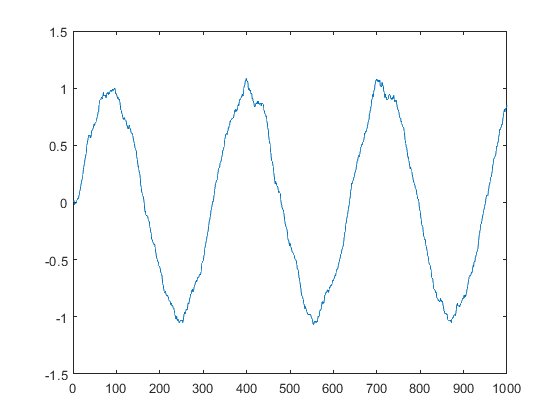

plot3 = plot(y3);

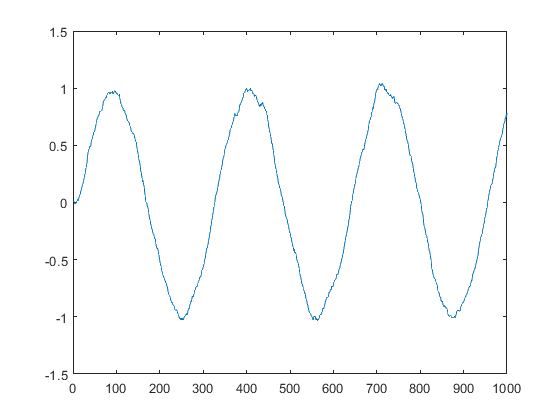

plot4 = plot(y4);

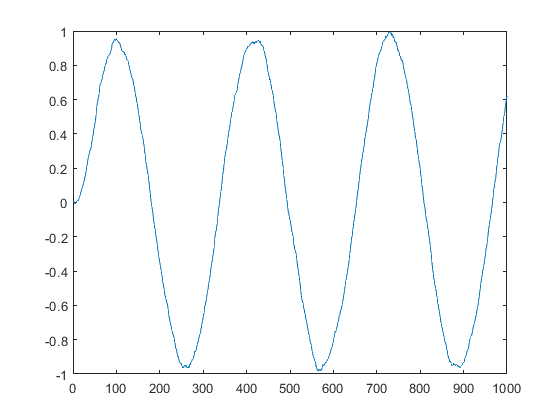

plot5 = plot(y5);


% --> the higher the length of b, the better (less noisy) the signal

## Question 3.3

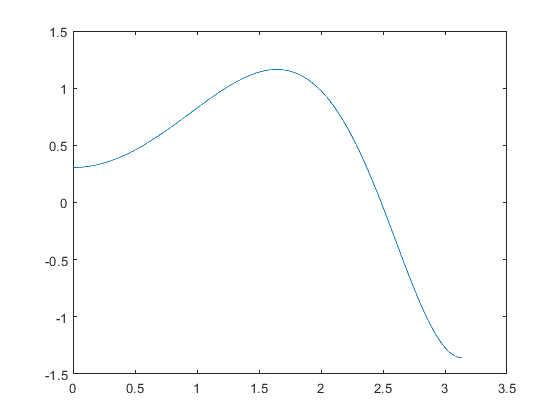

clear
load('data.mat');

% a)
omega = 2*pi*(50 - 102.4);
z1 = exp(1i*omega);
z2 = exp(-(1i)*omega);

b = [1 -(z1 + z2) (z1+z2)];
a = [1 - 0.9*(z1 + z2) 0.9^2 * z1 * z2];

[h,w] = freqz(b,a,512);
figure
plot(w,h)

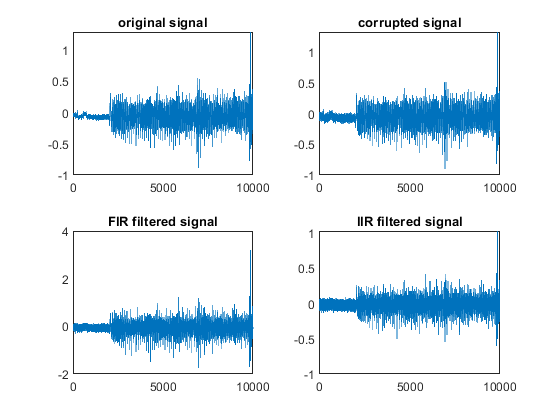


yFIR = filter(b,1,d1);
yIIR = filter(b,a,d1);


figure
subplot(2,2,1)
plot(data)
title('original signal')
subplot(2,2,2)
plot(d1)
title('corrupted signal')
subplot(2,2,3)
plot(yFIR);
title('FIR filtered signal')
subplot(2,2,4)
plot(yIIR)
title('IIR filtered signal')

## Question 3.4

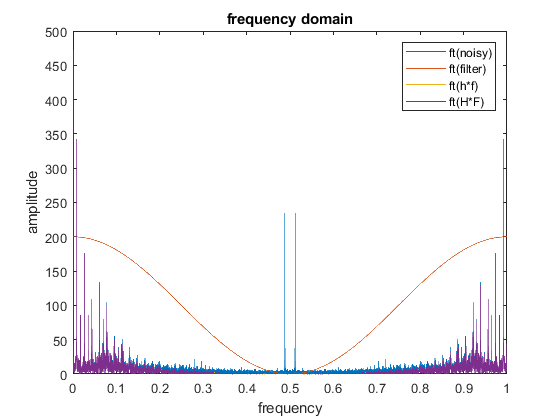

clear
load('data.mat');
h = [0.25 0.5 0.25];
y1 = filter(h,1,d1);

fq = 102.4;
t = ((0:length(y1)-1)*fq)/length(y1);

% normalized fq:
nfq  = (0:length(d1)-1)./length(d1);
omega = 2*pi*nfq;

H = 0.25 + 0.5*exp(1i*omega) + 0.25*exp(2i*omega);
F = fft(d1);
Y1 = fft(y1);
Y2 = H'.*F;

figure
plot(nfq,abs(F),nfq,200*abs(H),nfq,abs(Y1),nfq,abs(Y2))
legend('ft(noisy)', 'ft(filter)', 'ft(h*f)', 'ft(H*F)')
title('frequency domain')
xlabel('frequency')
ylabel('amplitude')

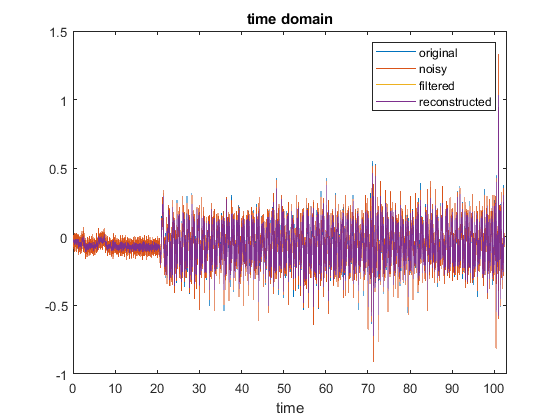


y2 = real(ifft(Y2));

figure
plot(t,data,t,d1,t,y1,t,y2)
legend('original', 'noisy', 'filtered', 'reconstructed')
axis([0,103,-1,1.5]);
title('time domain')
xlabel('time')


% check convolution theorem =0?:
ct = mean(abs(y1-y2))

ct = 4.1992e-06

## Question 3.5

clear

Im = [zeros(5,3),ones(5,2)]

Im =      0     0     0     1     1
     0     0     0     1     1
     0     0     0     1     1
     0     0     0     1     1
     0     0     0     1     1


h = ones(3,3)

h =      1     1     1
     1     1     1
     1     1     1



g = filter2(h,Im)

g =      0     0     2     4     4
     0     0     3     6     6
     0     0     3     6     6
     0     0     3     6     6
     0     0     2     4     4


## Question 3.6

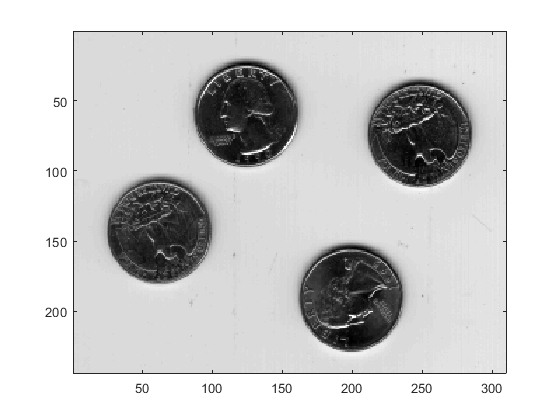

clear

im = imread('eight.tif');
imagesc(im)
colormap gray

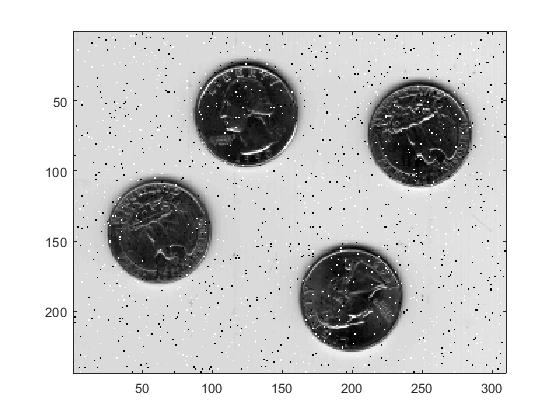


% salt-pepper: black & white pixels randomly spread 
% over img
im_sp = noise(im,'sp', 0.02);
imagesc(im_sp)
colormap gray 

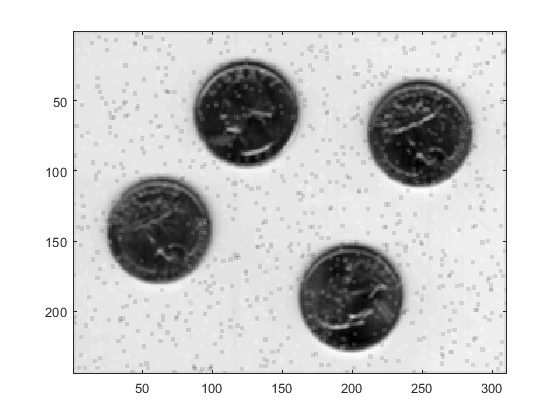


k1 = ones(3,3)/(3^2);
k2 = ones(5,5)/(5^2);
k3 = ones(15,15)/(15^2);

g1 = filter2(k1,im_sp);
g2 = filter2(k2,im_sp);
g3 = filter2(k3,im_sp);

imagesc(g1)
colormap gray

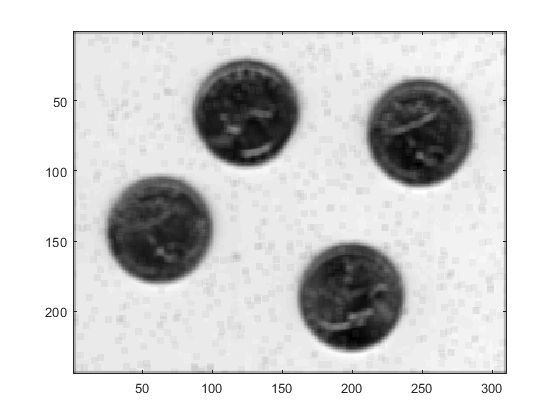

imagesc(g2)
colormap gray

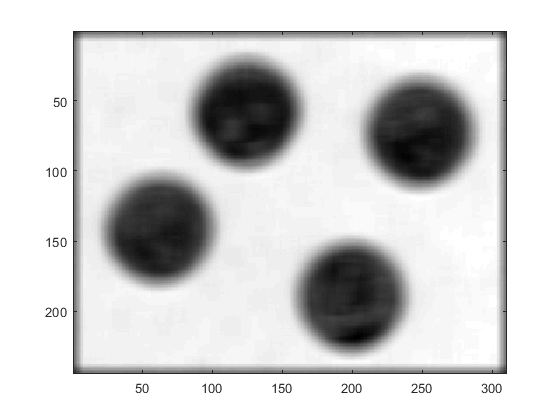

imagesc(g3)
colormap gray


% noise disappears -> mean filter useful for removing
% salt and pepper (since average of black and white is gray)
% but rest of image turns out blurry, too

## Question 3.7

% additive gaussian: 
imagesc(im)
colormap gray 

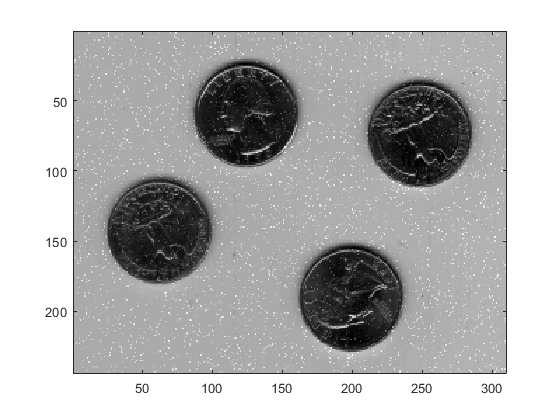

im_ag = noise(im,'au', 50, 0.07);
imagesc(im_ag)
colormap gray 

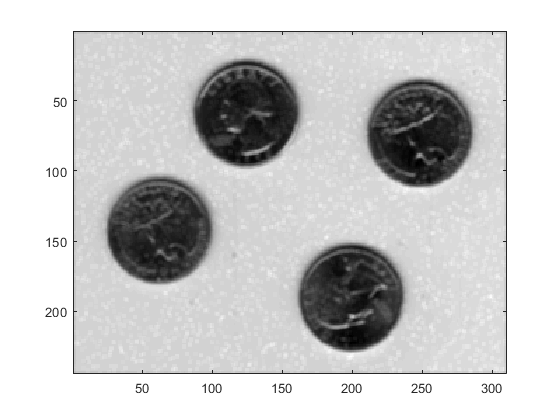


k1 = ones(3,3)/(3^2);
k2 = ones(5,5)/(5^2);
k3 = ones(15,15)/(15^2);

g4 = filter2(k1,im_ag);
g5 = filter2(k2,im_ag);
g6 = filter2(k3,im_ag);

imagesc(g4)
colormap gray

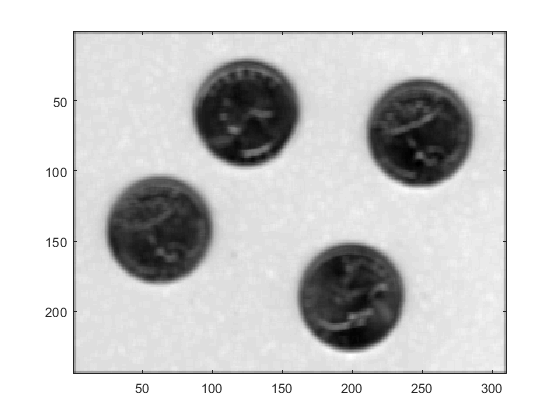

imagesc(g5)
colormap gray

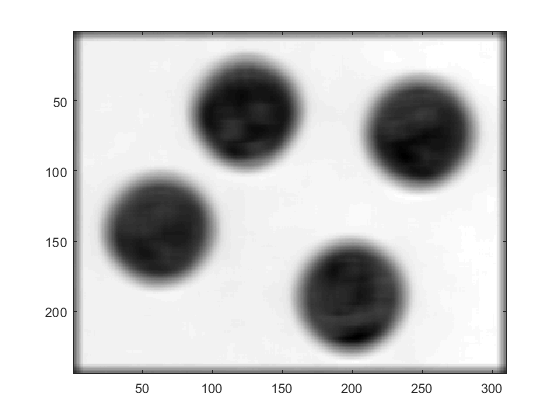

imagesc(g6)
colormap gray


% same thing?

## Question 3.8

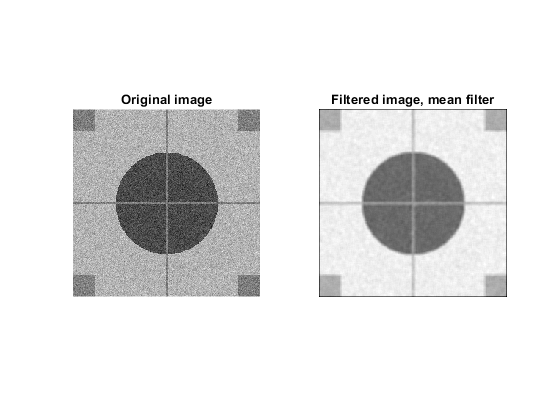

clear

im1 = imread('circle.bmp');
fsize = 5;
h = ones(fsize)/fsize^2;

meanim1 = filter2(h,im1);
meanim12 = filter2(h,im1,'same');
meanim13 = filter2(h,im1,'valid');
meanim14 = filter2(h,im1,'full');

figure
subplot(1,2,1);
imshow(im1,[]), colormap gray, axis image off;
title('Original image')
subplot(1,2,2);
imshow(meanim1,[]), colormap gray, axis image off;
title('Filtered image, mean filter')

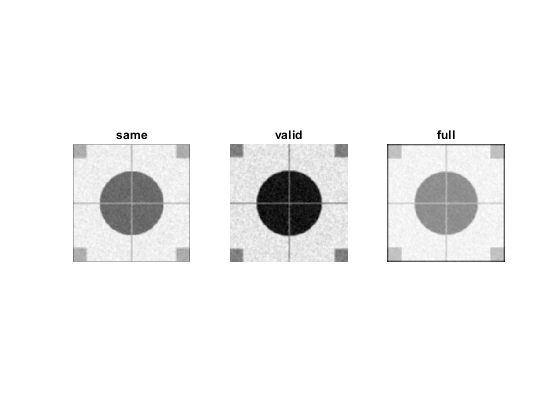


figure
subplot(1,3,1);
imshow(meanim12,[]), colormap gray, axis image off;
title('same')
subplot(1,3,2);
imshow(meanim13,[]), colormap gray, axis image off;
title('valid')
subplot(1,3,3);
imshow(meanim14,[]), colormap gray, axis image off;
title('full')